# Script di stima della RUL di motori di aerei

clc, close all, clear all

%%%%%%%%%%%%%%%%%%%%%%%%%%% INSERIRE PATH SPECIFICO PER UTENTE CORRENTE %%%%%%%%%%%%%%%%%%%%%%%%%%%
%path = 'C:/Users/sam/Desktop/PHM2021_Data_Challenge_Exam_Project/cluster_set/';
path = 'C:/Users/mat98/source/repos/PHM2021_Data_Challenge_Exam_Project/cluster_set/';
fileList = {'N-CMAPSS_cluster_0_cycle.csv', 'N-CMAPSS_cluster_1_cycle.csv', 'N-CMAPSS_cluster_2_cycle.csv'};
numeroClusters = length(fileList)

numeroClusters = 3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Costruzione Health Indicator


for num_cluster = 1:numeroClusters
    filename = string(append(path,fileList(num_cluster)));
    
    T = readtable(filename);

    % aggiunta istanti di tempo associati ad ogni misurazione dei sensori
    unita_totali = unique(T.unit);
    TT = timetable();
    for i=1:length(unita_totali)
        indici_righe = find(T.unit == unita_totali(i));
        T_filter = T(indici_righe, :);
        TT2 = array2timetable(T_filter, 'RowTimes', seconds(1:size(T_filter)));
        TT = vertcat(TT, TT2);
    end

    T = addvars(T, TT.Time, 'NewVariableNames', 'Time');

    
    % imposta il valore della percentuale
    perc_training = 0.7;
    
    % calcola la dimensione delle due parti
    n1 = floor(length(unita_totali) * perc_training);
    n2 = length(unita_totali) - n1;
    
    rng(42);
    
    indici = randperm(length(unita_totali));
        
    unita_training = unita_totali(indici(1:n1));
        
    unita_test = unita_totali(indici(n1+1:end));
    
    T_training = T(ismember(T.unit, unita_training), :);
    T_test = T(ismember(T.unit, unita_test), :);



    varNames = string(T.Properties.VariableNames);
    
    timeVariable = varNames(22);
    conditionVariables = varNames(17:20);
    dataVariables = varNames(1:14);

    clusterTrainNormal = cell(num_cluster,1);
    clusterValidNormal = cell(num_cluster,1);
    centerstats = struct('Mean', table(), 'SD', table());

    % Normalizzazione training
    for v = dataVariables
            centerstats(num_cluster).Mean.(char(v)) = mean(T_training.(char(v)));
            centerstats(num_cluster).SD.(char(v)) = std(T_training.(char(v)));
    end

    for motore=1:length(unita_training)
        tablesensNorm = table();
        indici_righe = find(T.unit == unita_training(motore));
        T_filter = T(indici_righe, :);
        for v = dataVariables
                tablesensNorm.Time = T_filter.Time;
                sensorToNorm = T_filter.(char(v));
                sensNorm = (sensorToNorm - centerstats(num_cluster).Mean.(char(v)))./centerstats(num_cluster).SD.(char(v));
                tablesensNorm.(char(v)) = sensNorm;
        end
        for z = conditionVariables
                tablesensNorm.(char(z)) = T_filter.(char(v));
        end
        clusterTrainNormal{num_cluster,1}{motore,1} = tablesensNorm;
        
    end

    % Normalizzazione test
    for v = dataVariables
            centerstats(num_cluster).Mean.(char(v)) = mean(T_test.(char(v)));
            centerstats(num_cluster).SD.(char(v)) = std(T_test.(char(v)));
    end
    
    for motore=1:length(unita_test)
        tablesensNorm = table();
        indici_righe = find(T.unit == unita_test(motore));
        T_filter = T(indici_righe, :);
        for v = dataVariables
                tablesensNorm.Time = T_filter.Time;
                sensorToNorm = T_filter.(char(v));
                sensNorm = (sensorToNorm - centerstats(num_cluster).Mean.(char(v)))./centerstats(num_cluster).SD.(char(v));
                tablesensNorm.(char(v)) = sensNorm;
        end
        for z = conditionVariables
                tablesensNorm.(char(z)) = T_filter.(char(v));
        end
        clusterValidNormal{num_cluster,1}{motore,1} = tablesensNorm;
        
    end

    %% trendability analysis on each sensor
    numSensors = length(dataVariables);
    signalSlope = zeros(numSensors, 1);
    warn = warning('off');
    for ct = 1:numSensors
        tmp = cellfun(@(tbl) tbl(:, cellstr(dataVariables(ct))), clusterTrainNormal{num_cluster,1}, 'UniformOutput', false);
        %mdl = linearDegradationModel(); % create model
        mdl = exponentialDegradationModel();
        fit(mdl, tmp); % train mode
        signalSlope(ct) = mdl.Theta;    
    end
    warning(warn);

    % prendiamo gli 8 sensori che hanno valori di Theta maggiori, ovvero
    % gli 8 che hanno più pendenza, che sono più rappresentativi
    [~, idx] = sort(abs(signalSlope), 'descend');
    sensorTrended = sort(idx(1:8));

     5
     6
     7
    12



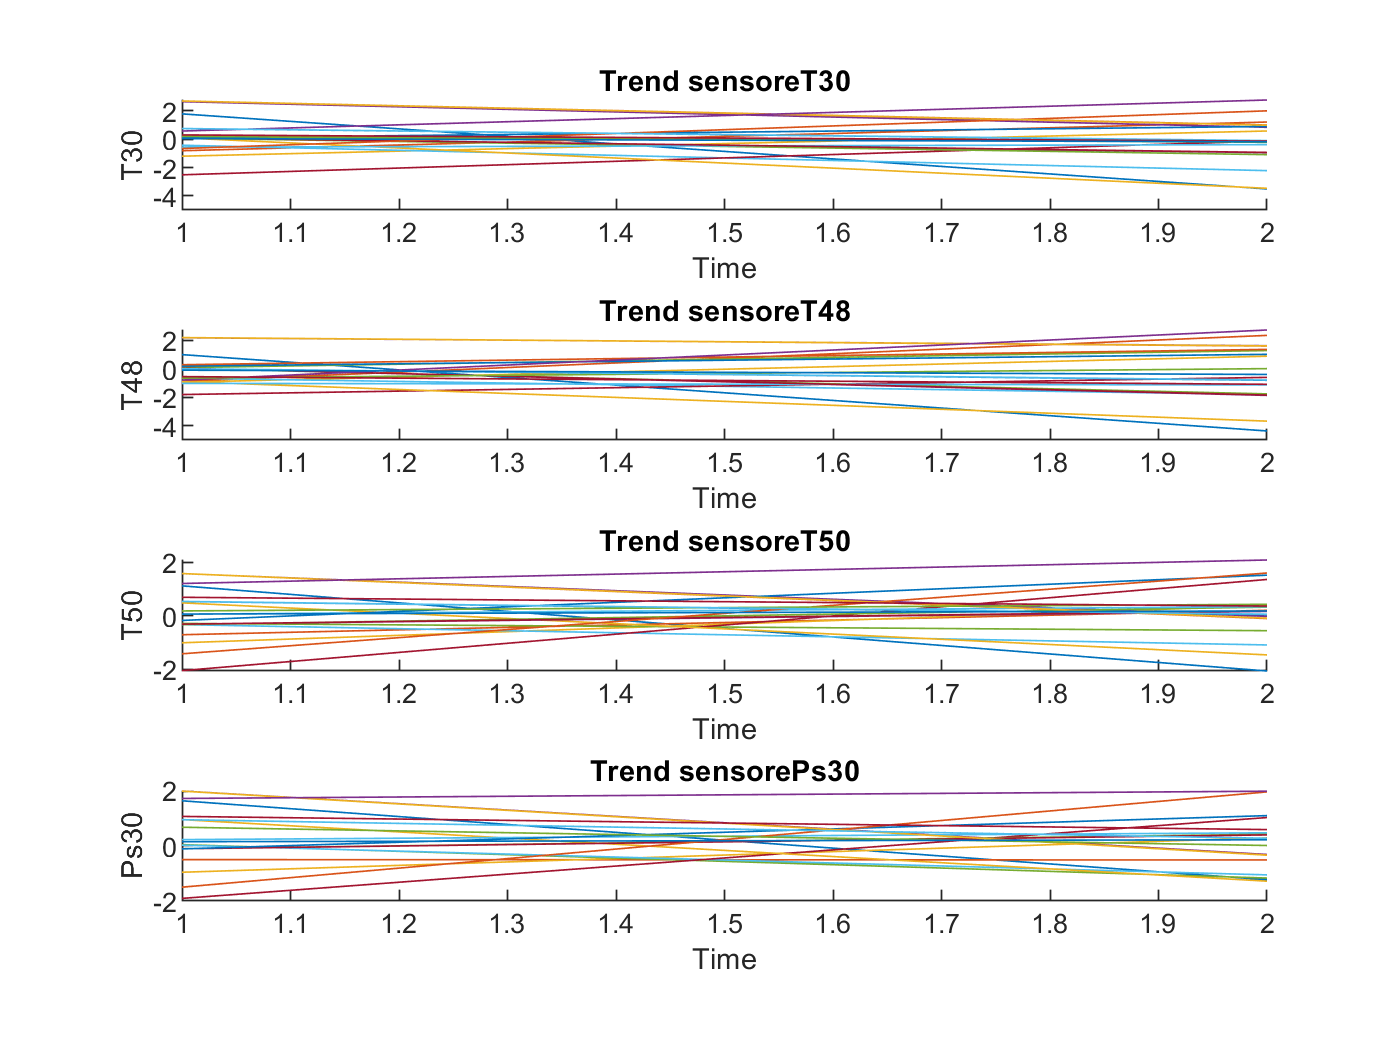

     6
     7
     9
    10



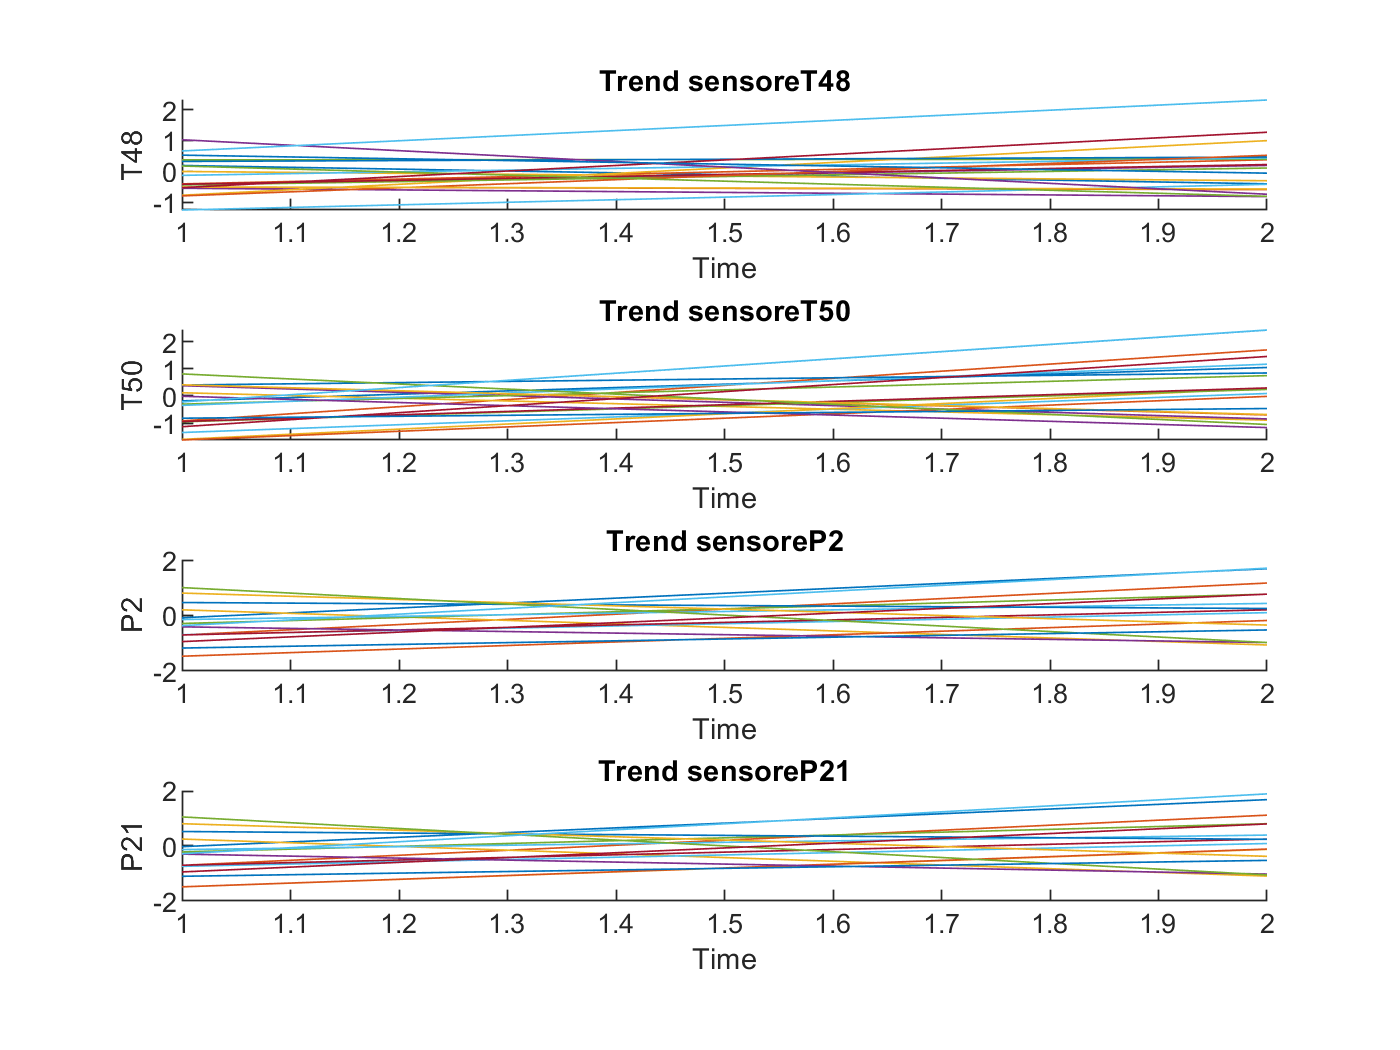

     8
     9
    10
    11



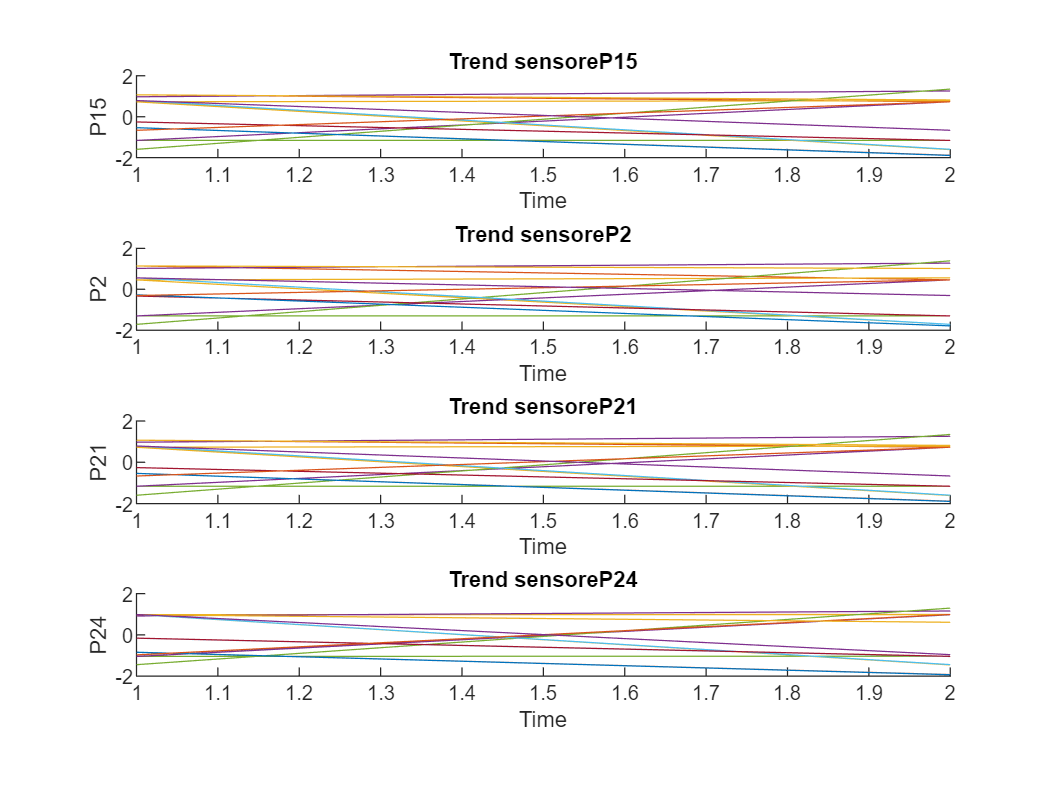

    nsample = 50;
    helperPlotEnsemble(clusterTrainNormal{num_cluster,1}, sensorTrended, dataVariables, nsample)

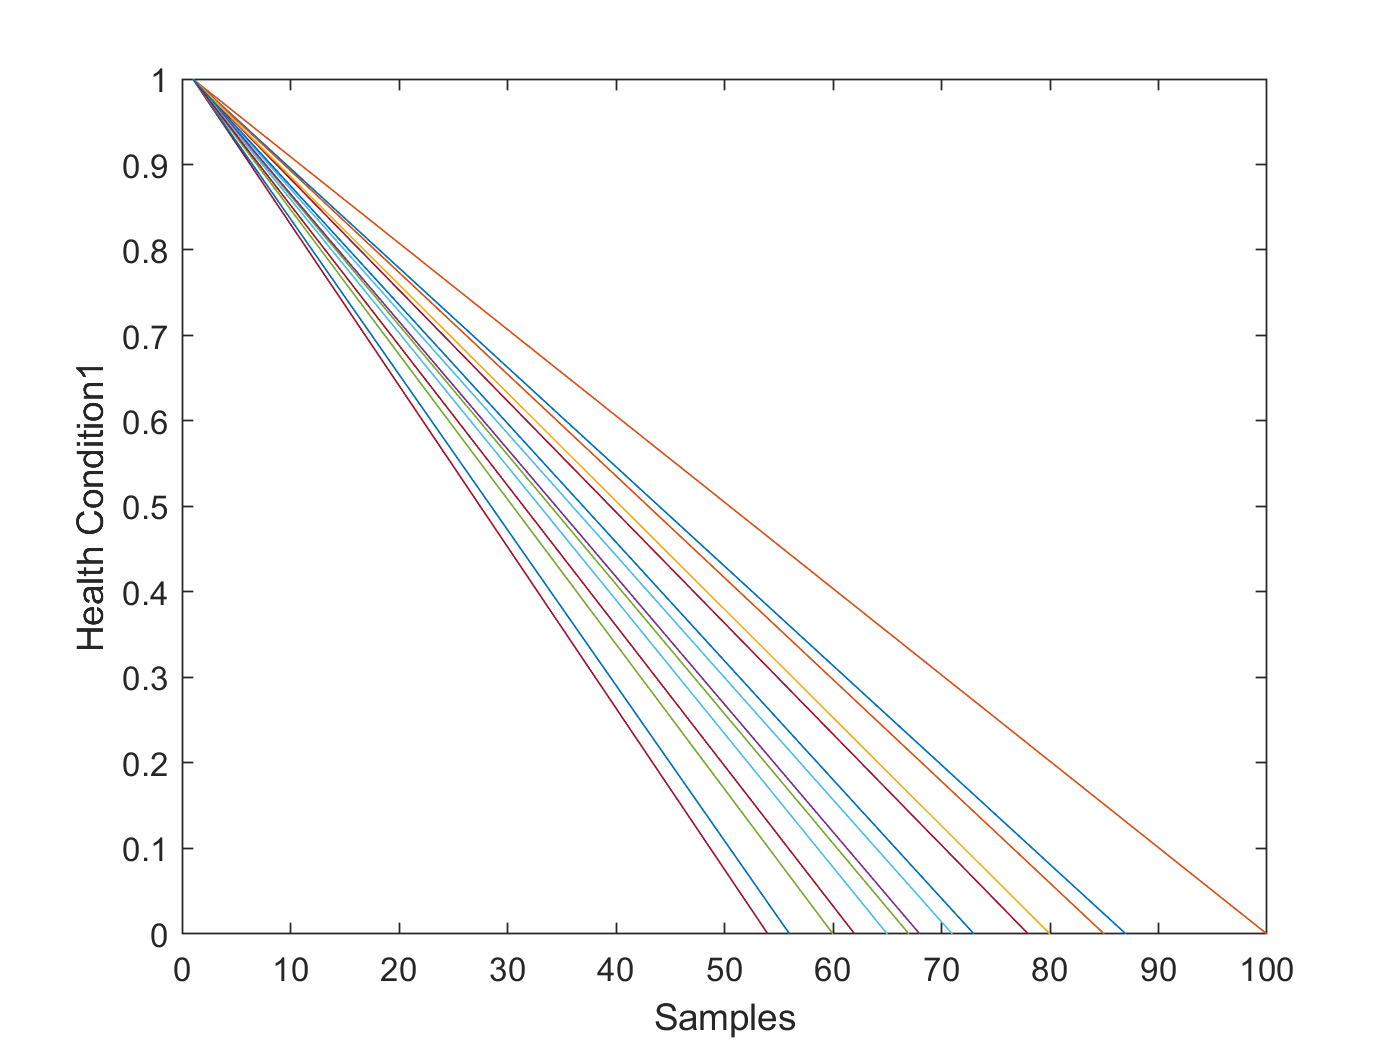

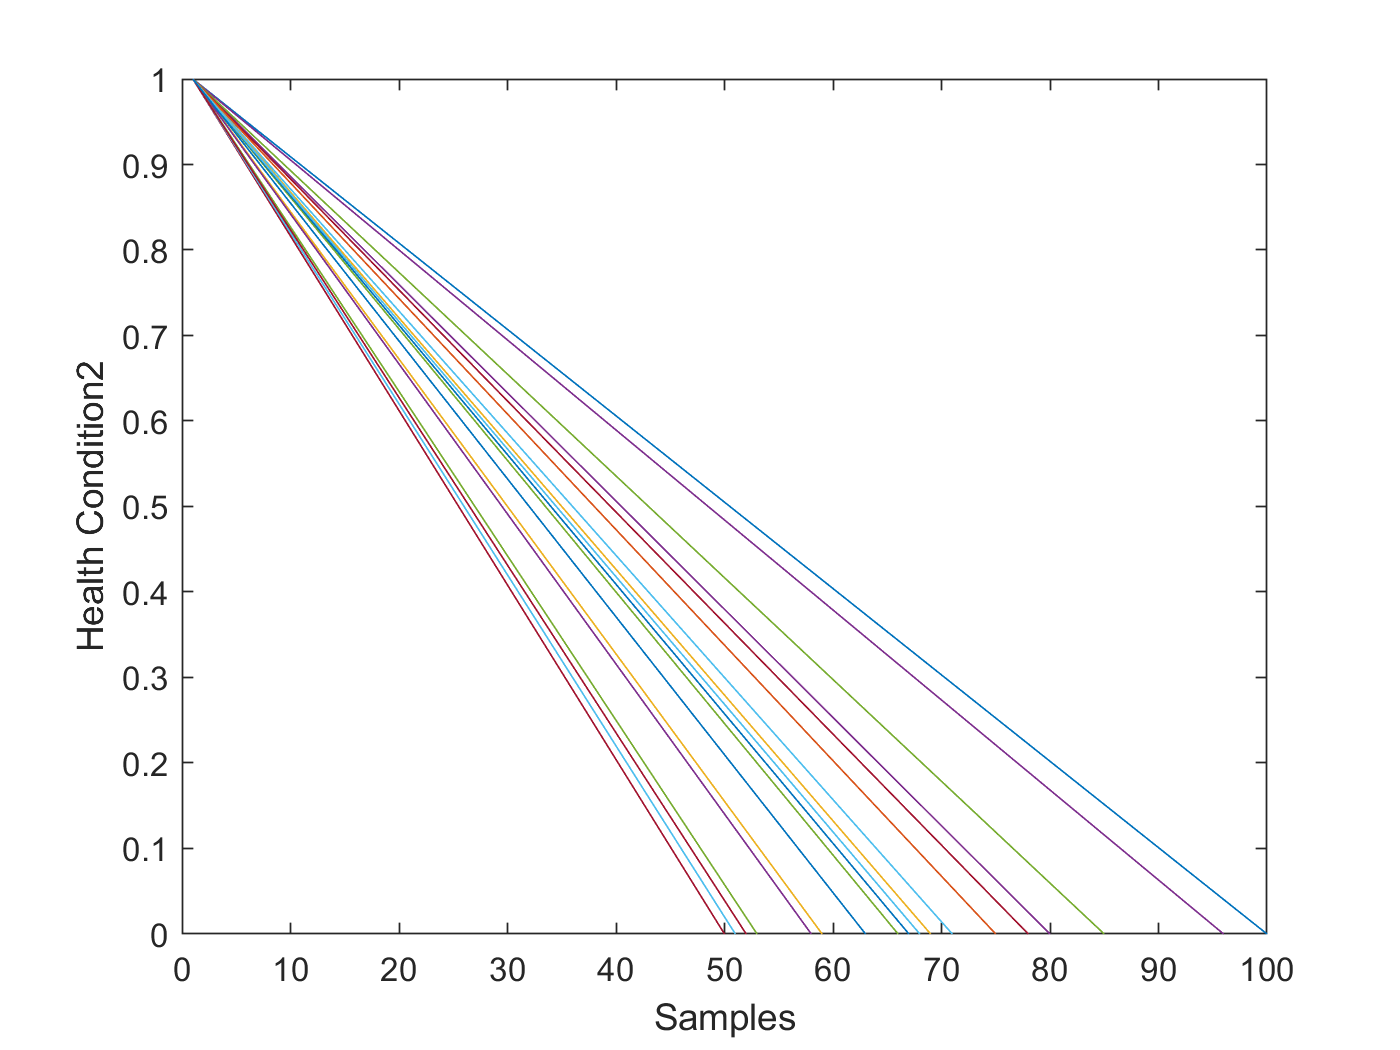

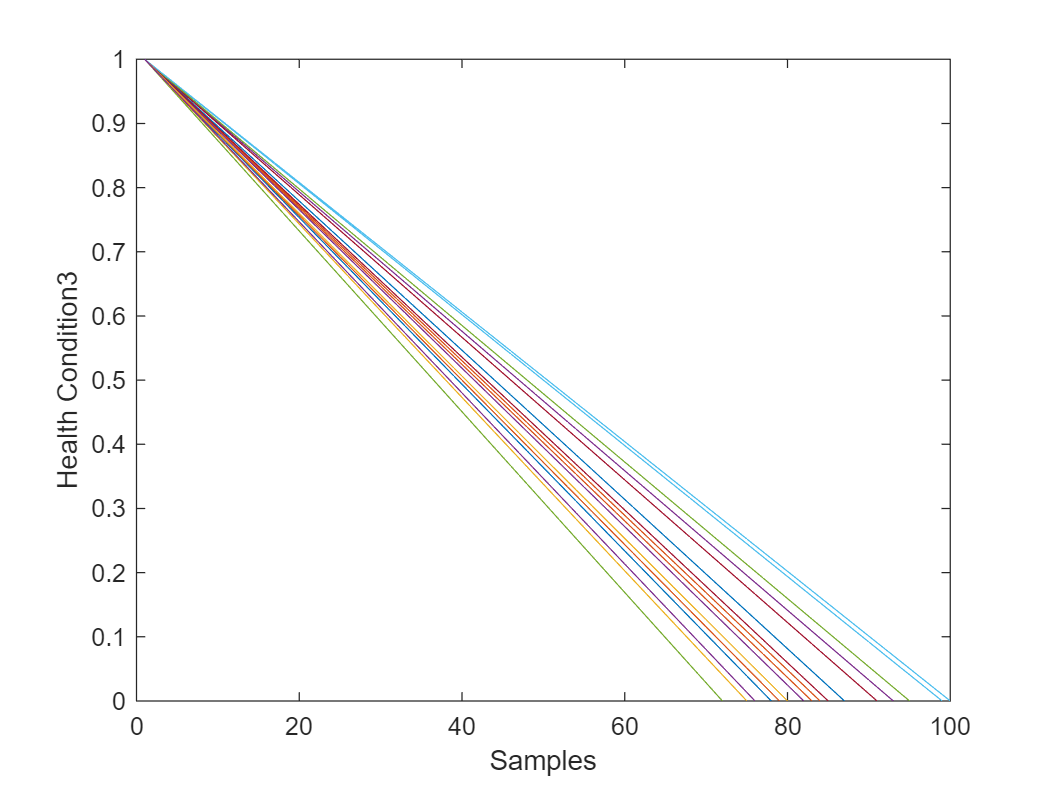

    figure
        for motore = 1:numel(clusterTrainNormal{num_cluster,1})
            data = clusterTrainNormal{num_cluster,1}{motore};
            rul = max(data.Time)-data.Time;
            data.health_condition = rul / max(rul);
            clusterTrainNormal{num_cluster,1}{motore} = data;
        
            plot(clusterTrainNormal{num_cluster,1}{motore}.health_condition)
            % title('trainData');
            ylabel("Health Condition"+string(num_cluster));
            xlabel("Samples");
            hold on
        end

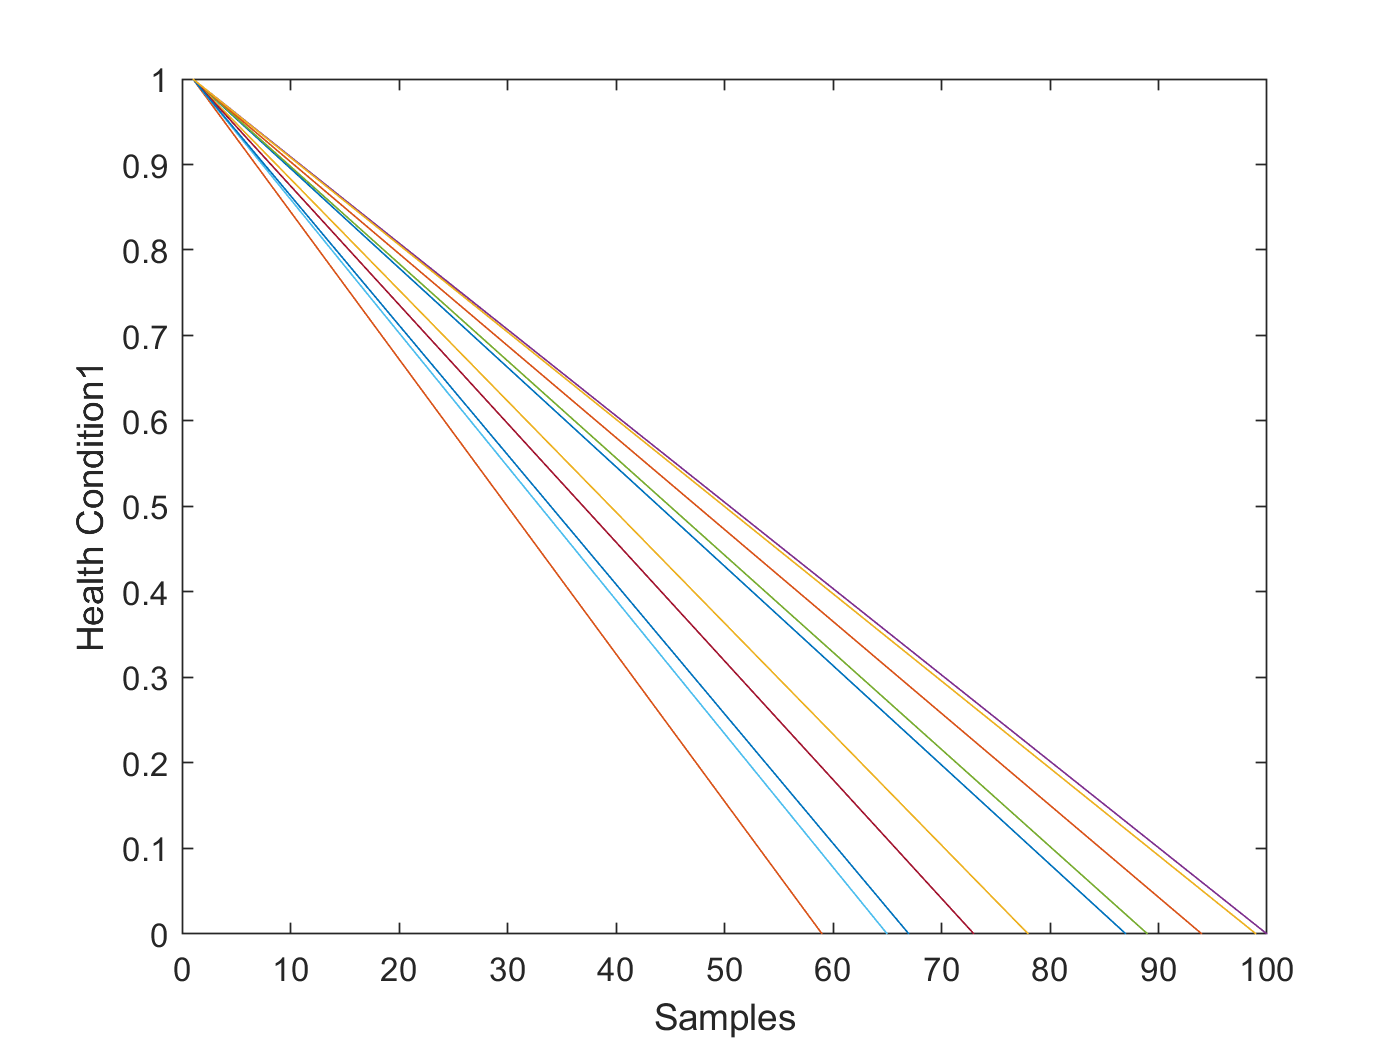

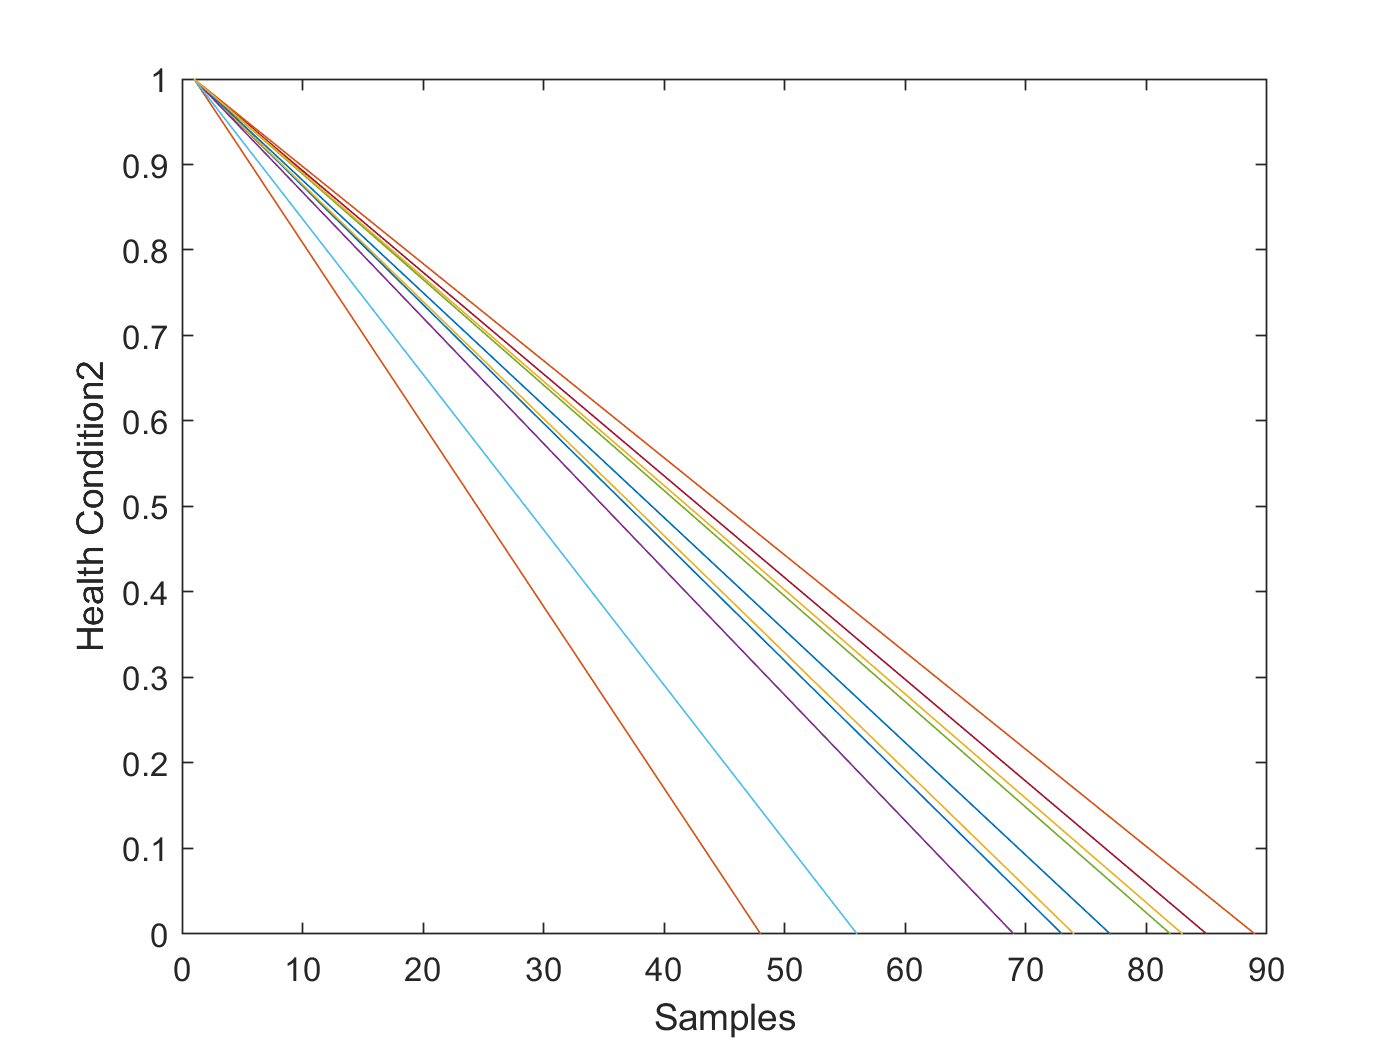

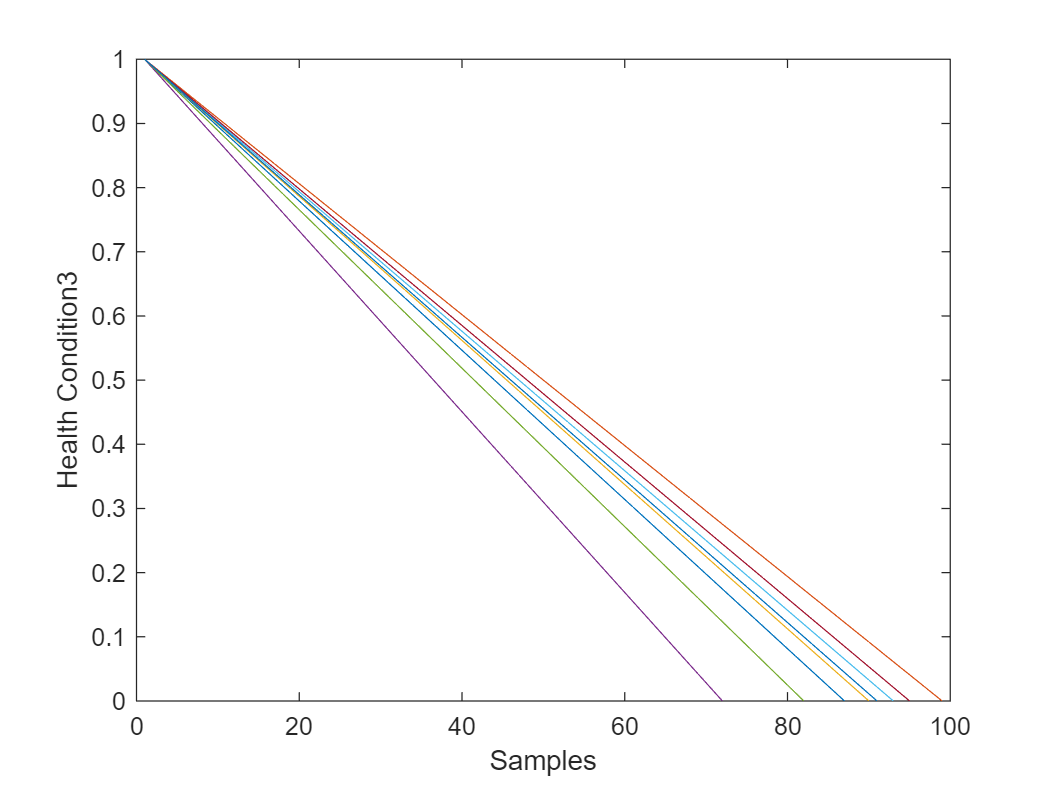

        
        figure
        for motore = 1:numel(clusterValidNormal{num_cluster,1})
            data = clusterValidNormal{num_cluster,1}{motore};
            rul = max(data.Time)-data.Time;
            data.health_condition = rul / max(rul);
            clusterValidNormal{num_cluster,1}{motore} = data;
        
            plot(clusterValidNormal{num_cluster,1}{motore}.health_condition)
            % title('validationData');
            ylabel("Health Condition"+string(num_cluster));
            xlabel("Samples");
            hold on
        end

     %% fitting linear model for unified health indicator
        trainDataNormalizedUnwrap = vertcat(clusterTrainNormal{num_cluster,1}{:});
        
        sensorToFuse = dataVariables(sensorTrended);
        X = trainDataNormalizedUnwrap{:, cellstr(sensorToFuse)};
        y = trainDataNormalizedUnwrap.health_condition;
        regModel = fitlm(X,y);

        
        bias = regModel.Coefficients.Estimate(1)

bias = 0.5000

bias = 0.5000

bias = 0.5000

        weights = regModel.Coefficients.Estimate(2:end)

weights =    -0.2453
   -0.1158
    0.0145
    0.0369
   -0.0750
   -9.3371
    9.5651
   -0.0719


weights =    -0.2847
    0.0078
   -0.1416
   -0.4367
   -6.6884
    7.6429
   -6.1944
    5.8740


weights =    -0.2036
   -0.3115
   -1.8472
    1.0939
         0
    0.1698
    1.9769
   -0.9730


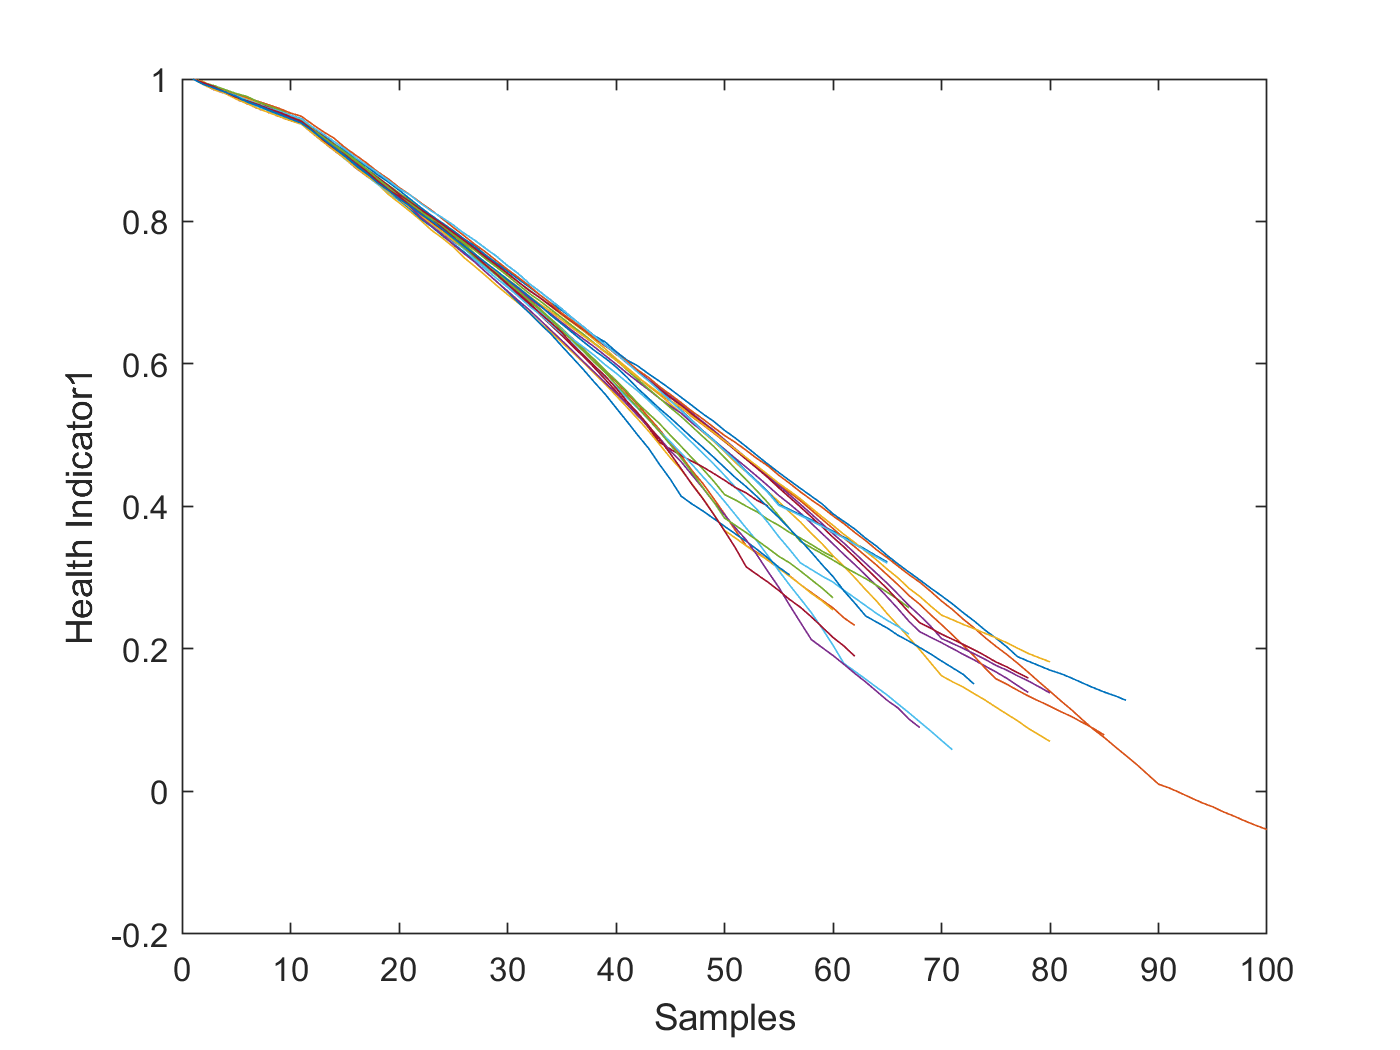

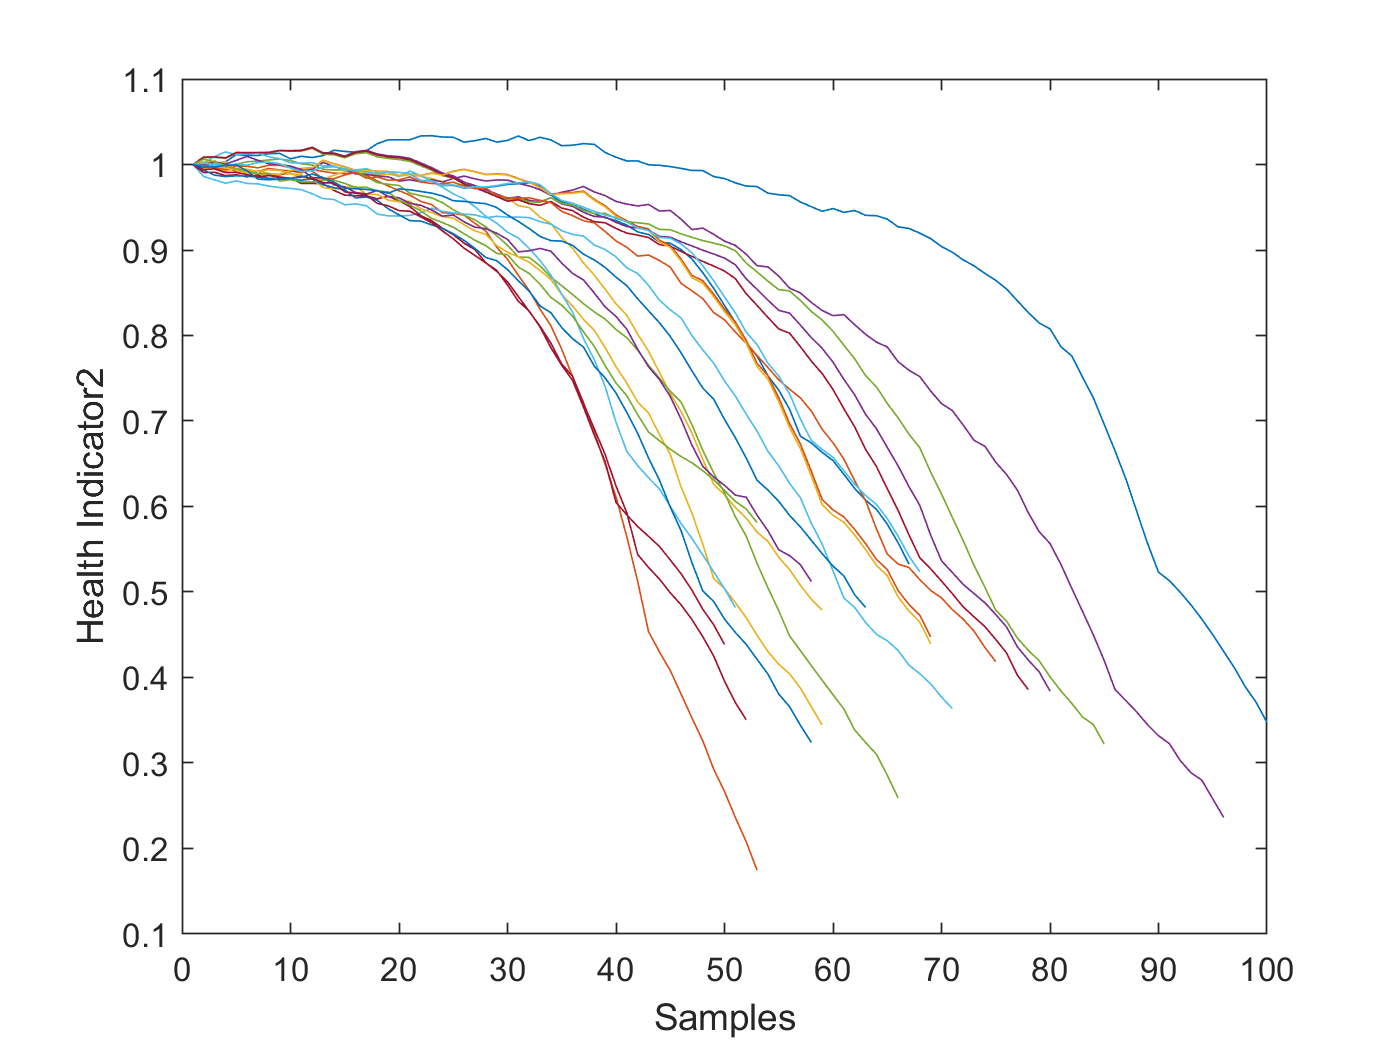

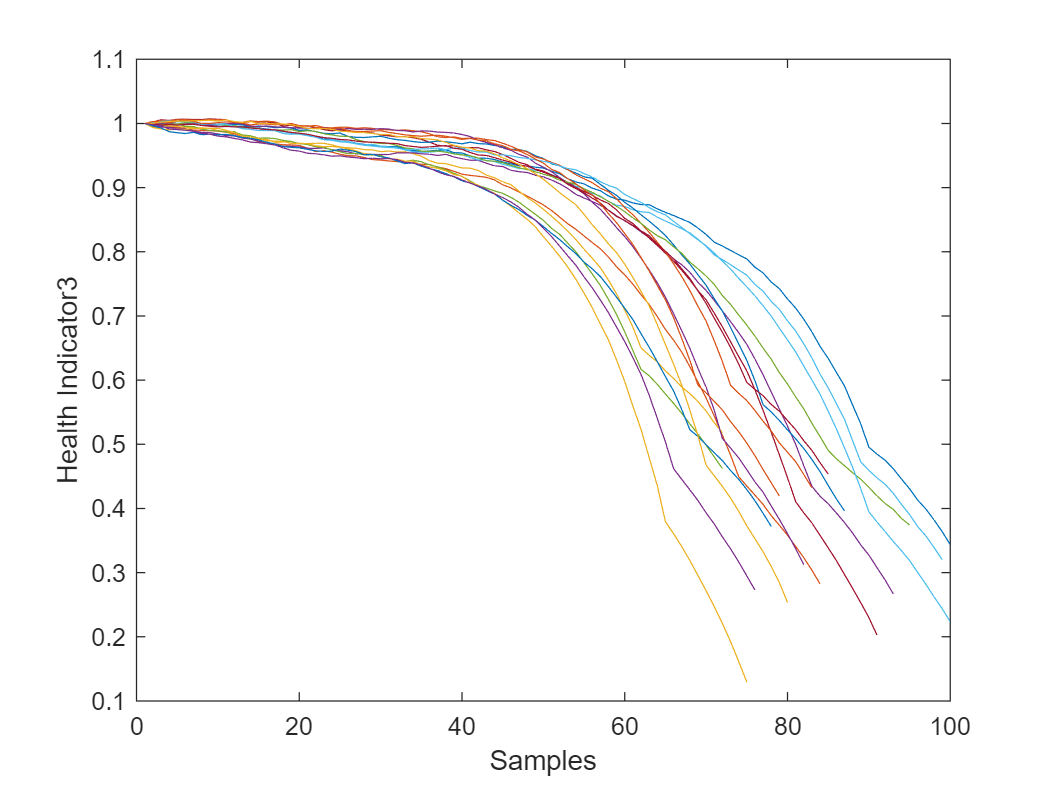

        
        
        %% unified health condition
        trainDataFused{num_cluster,1} = cellfun( @(data) degradationSensorFusion(data, sensorToFuse, weights), clusterTrainNormal{num_cluster,1}, ...
            'UniformOutput', false);
        %if num_cluster == 2
        %    trainDataFused{num_cluster,1}=trainDataFused{num_cluster,1}([1:2,4:end]);
        %end 
     
        validationDataFused{num_cluster,1} = cellfun(@(data) degradationSensorFusion(data, sensorToFuse, weights), ...
            clusterValidNormal{num_cluster,1}, 'UniformOutput', false);
        
        figure
        for k = 1:length(trainDataFused{num_cluster,1})
            plot(trainDataFused{num_cluster,1}{k})
            % title('trainDataFused')
            xlabel('Samples')
            ylabel('Health Indicator'+string(num_cluster))
            % title('Training Data')
            hold on
        end

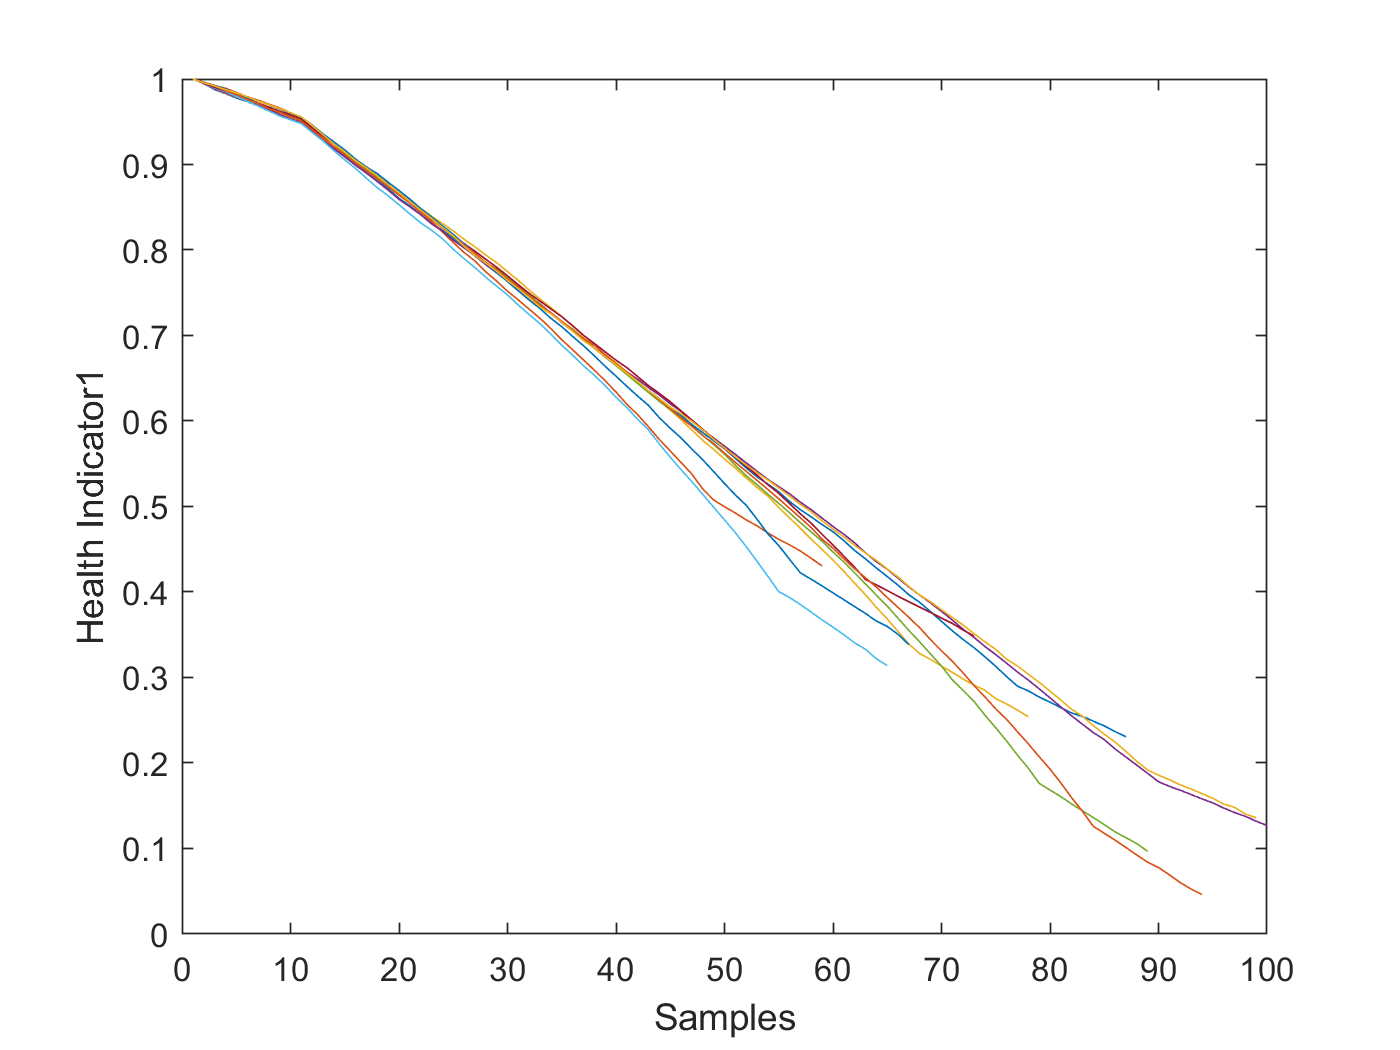

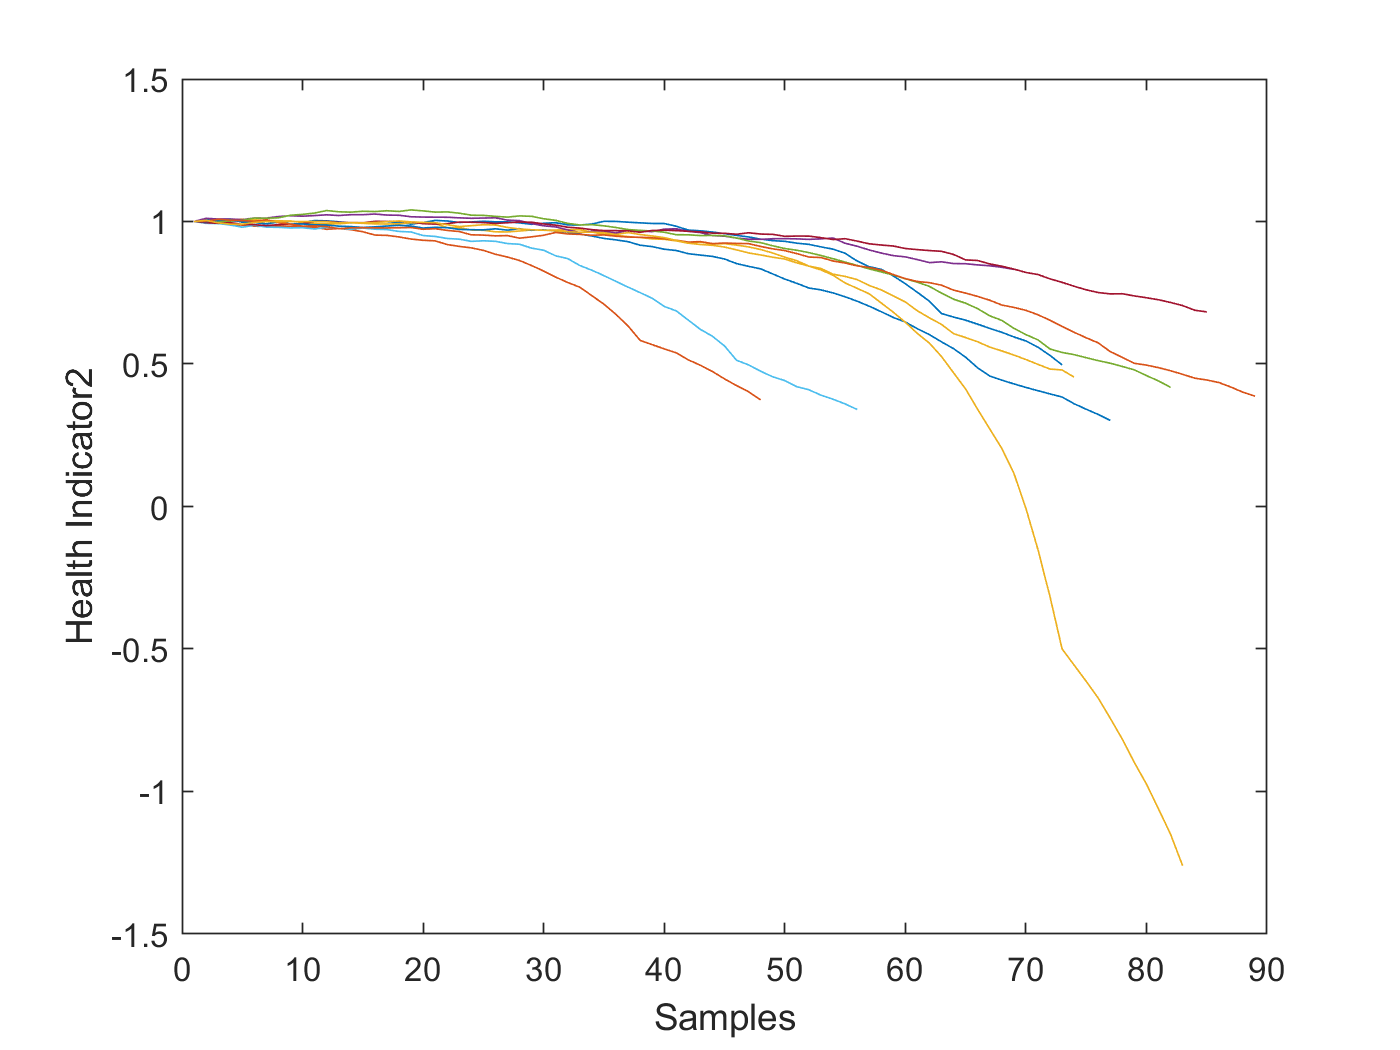

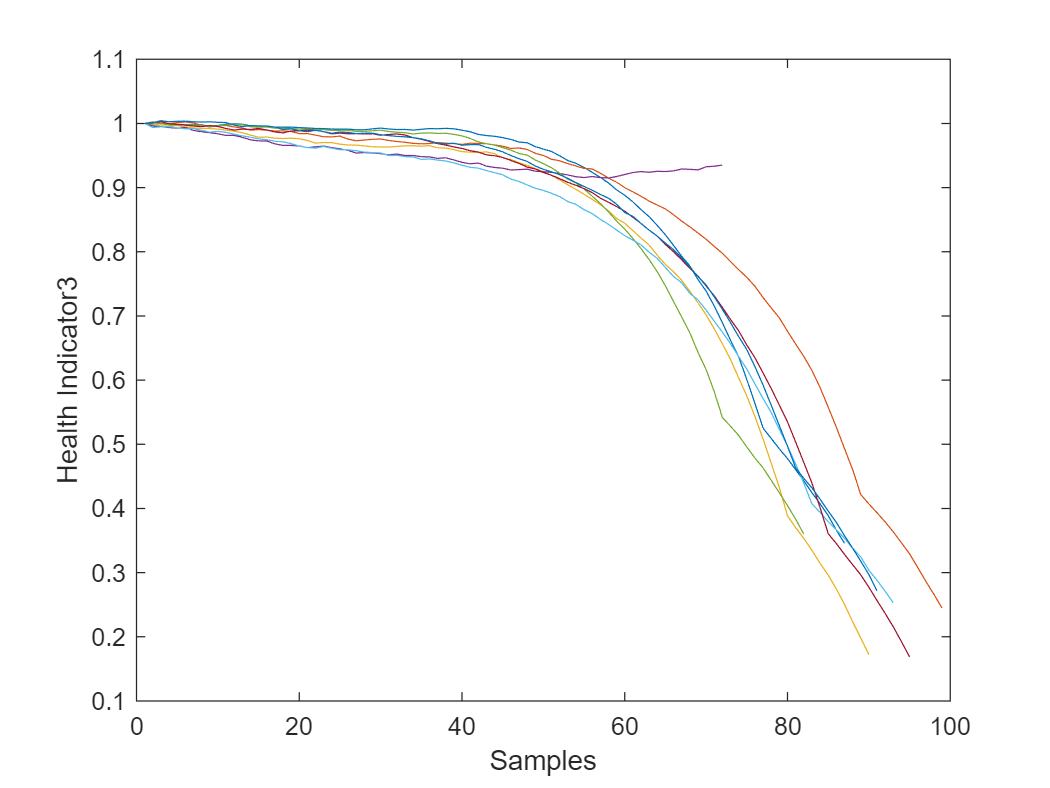

        
        figure
        for k = 1:length(validationDataFused{num_cluster,1})
            plot(validationDataFused{num_cluster,1}{k})
            % title('validationDataFused')
            xlabel('Samples')
            ylabel('Health Indicator'+string(num_cluster))
            % title('ValidationDataFused')
            hold on
        end

 end

function [] = helperPlotEnsemble(trainDataNormalized, sensorTrended, dataVariables, nsample)

    colonne = sensorTrended(3:6)+1;
    disp(colonne)
    [row,~] = size(trainDataNormalized);
    
    figure
    title('Trend sensori')
    for i = 1:length(colonne)
        subplot(4,1,i)
        for j = 1:row
            hold on
            y = trainDataNormalized{j,1}.(colonne(i))(1:nsample:end);
            plot(y)
            xlabel('Time')
            ylabel(string(dataVariables(colonne(i)-1)))
            title(strcat('Trend sensore ',string(dataVariables(colonne(i)-1))))
        end
        hold off
    end
    hold off
    end
function dataFused = degradationSensorFusion(data, sensorToFuse, weights)
% Combine measurements from different sensors according 
% to the weights, smooth the fused data and offset the data
% so that all the data start from 1

    % Fuse the data according to weights
    dataToFuse = data{:, cellstr(sensorToFuse)};
    dataFusedRaw = dataToFuse*weights;
    
    % Smooth the fused data with moving mean
    stepBackward = 10;
    stepForward = 10;
    dataFused = movmean(dataFusedRaw, [stepBackward stepForward]);
    
    % Offset the data to 1
    dataFused = dataFused + 1 - dataFused(1);
end

